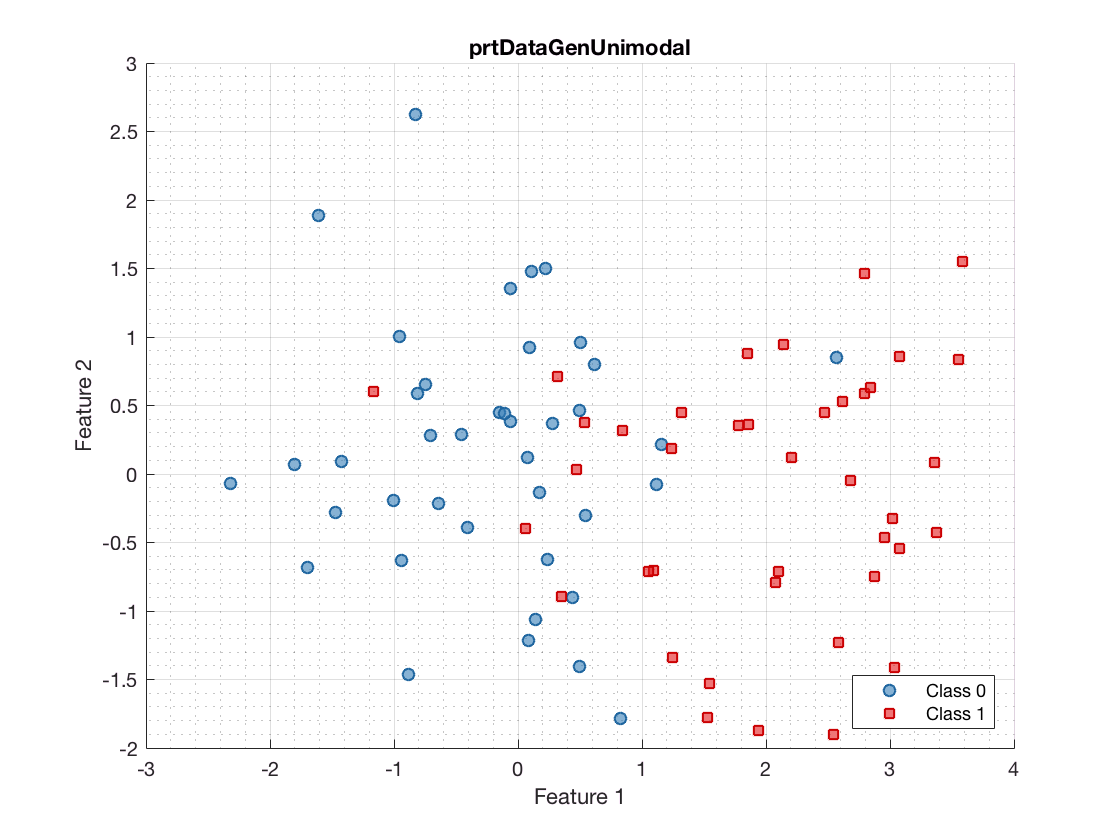

ds = prtDataGenUnimodal(40,[0,0],[2,0],eye(2),eye(2));
plot(ds)

N = ds.nObservations;
k = 4;
keys = [];
for iFold = 1:k
    keys = cat(1,keys,ones(N/k,1)*iFold);
end
keys = keys(randperm(N));

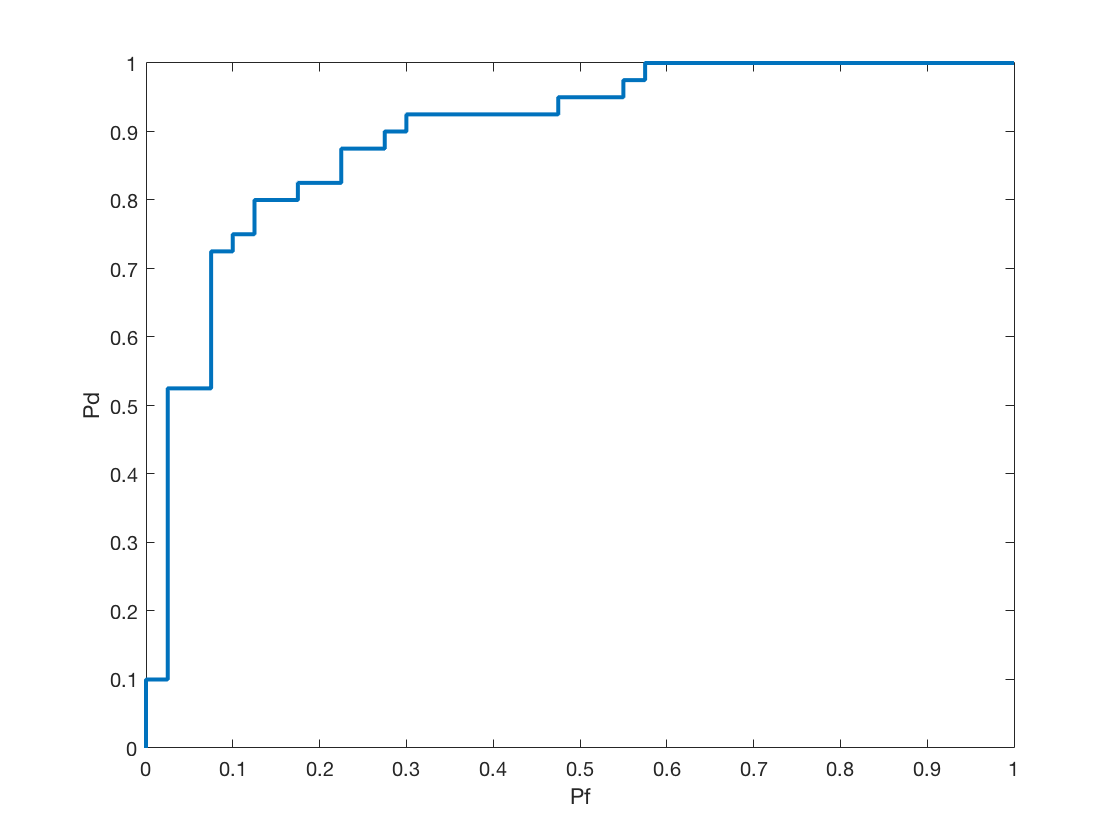

cls = prtClassFld;
results = prtDataSetClass;
for iFold = 1:k
    ds_train = ds.retainObservations(keys~=iFold);
    ds_test = ds.retainObservations(keys==iFold);
    cls_trained = cls.train(ds_train);
    results = results.catObservations(cls_trained.run(ds_test));
end
prtScoreRoc(results)

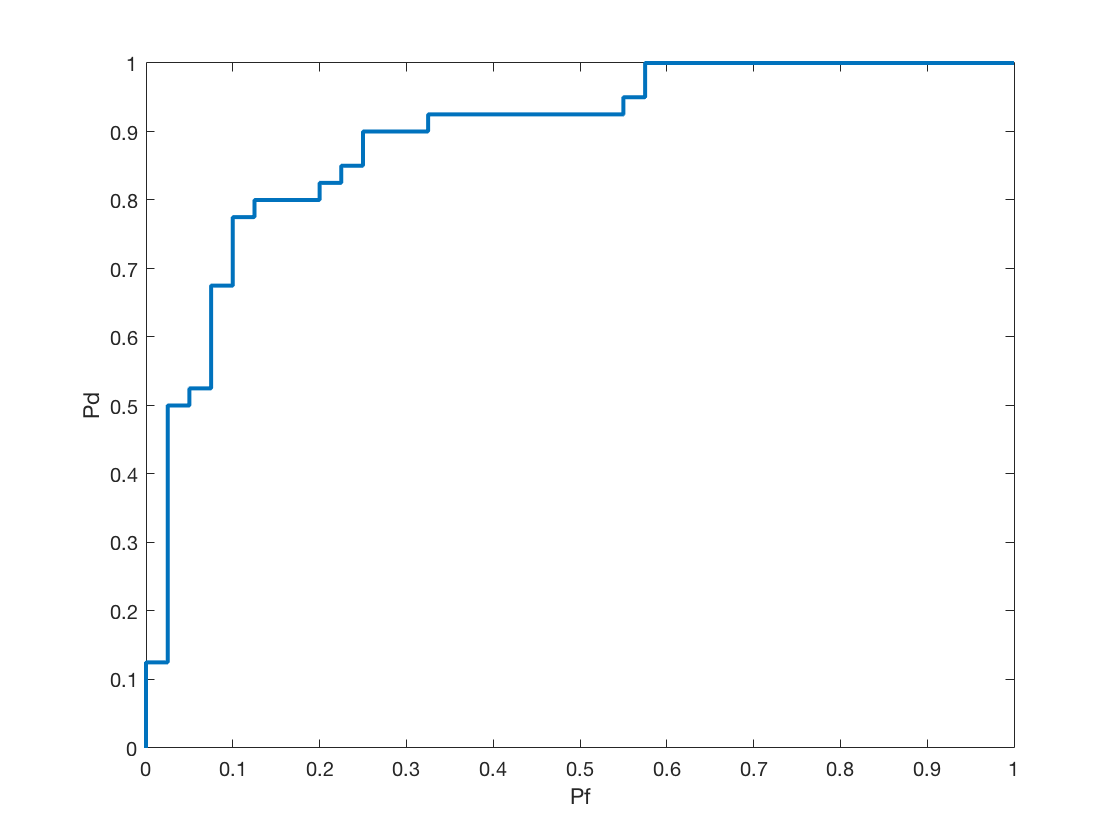

results = cls.kfolds(ds, k);
prtScoreRoc(results)